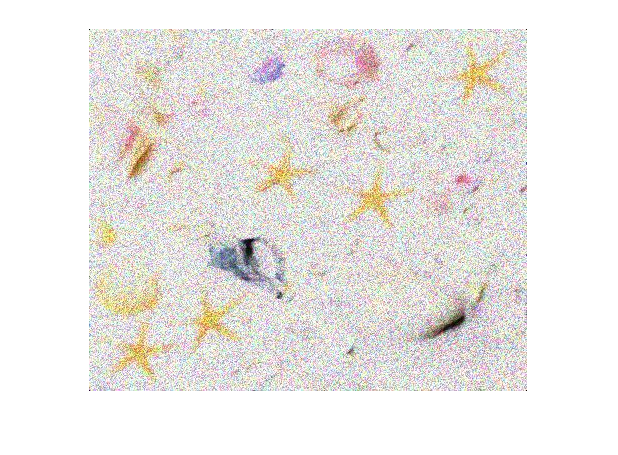

clear
im = imread("images\starfish_noise10.jpg");
imshow(im);

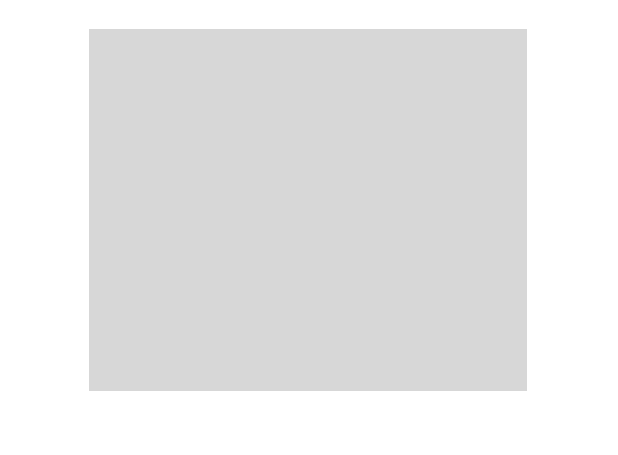


[noisyImages, labels] = GetNoises(im);

k = GetClosestNoiseType(im, noisyImages);
disp(labels{k});

Salt & Pepper


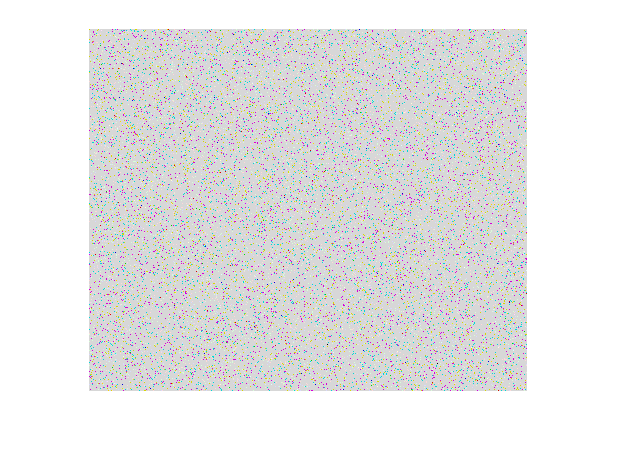

imshow(noisyImages{k});

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end

% function [noisyImages, labels] = GetNoises()
%     noisyImages = cell(6, 1);    
%     im = imread("images\starfish_map0.jpg");
%     
%     % Noise variations applied to map0;    
%     sp = imnoise(im, 'salt & pepper');
%     noisyImages{1} = sp;
%     labels{1} = "Salt & Pepper";
%     
%     g = imnoise(im, 'gaussian');
%     noisyImages{2} = g;
%     labels{2} = "Gaussian";
%     
% %     p = imnoise(im, 'poisson');
% %     noisyImages{3} = p;
% %     labels{3} = "Poisson";
%     
%     s = imnoise(im, 'speckle');
%     noisyImages{3} = s;
%     labels{3} = "Speckle";
%     
%     gsp = imnoise(g, 'salt & pepper');
%     noisyImages{4} = gsp;
%     labels{4} = "Gaussian + Salt & Pepper";
%     
%     gs = imnoise(g, 'speckle');
%     noisyImages{5} = gs;
%     labels{5} = "Gaussian + Speckle";
%     
%     ssp = imnoise(s, 'salt & pepper');
%     noisyImages{6} = ssp;
%     labels{6} = "Speckle + Salt & Pepper";
% end

function [noisyImages, labels] = GetNoises(im)
    noisyImages = cell(7, 1);
    [h,w,c] = size(im);
    avgLevel = mean2(im(:));
    im = avgLevel * ones(h, w, c, 'uint8');
    imshow(im);

    sp = imnoise(im, 'salt & pepper');
    noisyImages{1} = sp;
    labels{1} = "Salt & Pepper";
    
    g = imnoise(im, 'gaussian');
    noisyImages{2} = g;
    labels{2} = "Gaussian";
    
    p = imnoise(sp, 'poisson');
    noisyImages{3} = p;
    labels{3} = "Salt & Pepper + Poisson";
    
    s = imnoise(im, 'speckle');
    noisyImages{4} = s;
    labels{4} = "Speckle";
    
    gsp = imnoise(g, 'salt & pepper');
    noisyImages{5} = gsp;
    labels{5} = "Gaussian + Salt & Pepper";
    
    gs = imnoise(g, 'speckle');
    noisyImages{6} = gs;
    labels{6} = "Gaussian + Speckle";
    
    ssp = imnoise(s, 'salt & pepper');
    noisyImages{7} = ssp;
    labels{7} = "Speckle + Salt & Pepper";
end

function k = GetClosestNoiseType(im, noisyImages)
    diffs = cell(7, 1);
    closest = 0;
    
    [h,w,c] = size(im);
    if (h > w)
        im = rot90(im);
    end
    
    for i = 1:7
        diffs{i} = noisyImages{i} - im;
        diffSum = sum(diffs{i}(:));
        
        if (diffSum < closest || i == 1)
            closest = diffSum;
            k = i;
        end
    end
end